# Convolution Animation

clear;clc;

s = tf('s');
lambda = 1;
sys = 1/(s+lambda);

dt = 0.1;
T = 15;
t = 0:dt:T-dt;
N = length(t);
u = 0*t;
u(N/3:2*N/3) = 1;

[yimp,timp] = impulse(sys,t);

tsol = 0:dt:2*T-dt;
ysol = 0*tsol;

## Animate

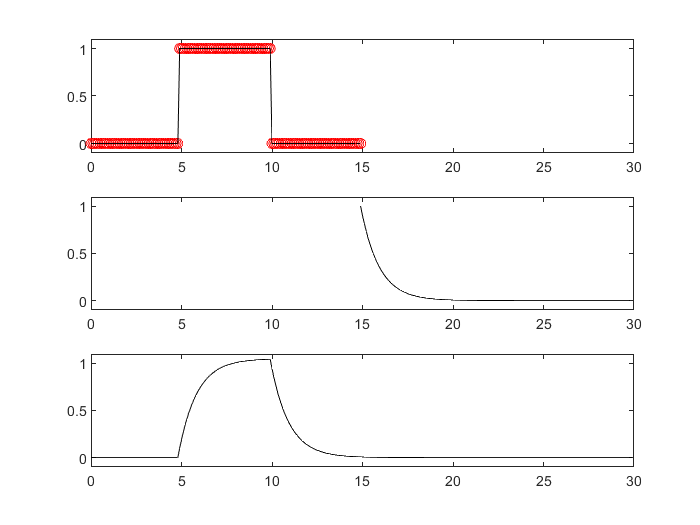

for k=1:length(u)
    subplot(3,1,1);
    plot(t,u,'k');
    axis([0 2*T -0.1 1.1])
    hold on;
    plot(t(k),u(k),'ro');
    
    subplot(3,1,2);
    plot(timp+t(k),yimp,'k');
    axis([0 2*T -0.1 1.1])
    
    ysol(k:k-1+length(t)) = ysol(k:k-1+length(t)) + yimp'*u(k)*dt;
    subplot(3,1,3);
    plot(tsol,ysol,'k');
    axis([0 2*T -0.1 1.1])
    
    drawnow;
end